tic
clc;clear all

fprintf('待分析點雲\r\n');

待分析點雲


cla_data = open_and_importdata('D:\論文\1080911\full\20210415\C6\4F');
cla_data = cla_data(:,1:3)

cla_data =     3.4128    3.4311    0.4036
    3.4066    3.4254    0.4158
    3.4059    3.4261    0.4070
    3.4037    3.4311    0.4236
    3.4065    3.4246    0.6482
    3.4065    3.4245    0.6399
    3.4153    3.4262    0.6536
    3.4058    3.4260    0.6653
    3.4067    3.4237    0.6570
    3.4138    3.4283    0.6619




%% 計算各點代表之直線向量

cla_r = 0.05; %閥值
cla_N_point = size(cla_data,1); %point_number


for cla_ii1 = 1:1:cla_N_point
    p = ones(cla_N_point,3)*[cla_data(cla_ii1,1) , 0 , 0 ; 0 , cla_data(cla_ii1,2) , 0 ; 0 , 0 , cla_data(cla_ii1,3)]; %選取點之座標
    D = sum((cla_data - p).^2,2).^(0.5); %最小二乘法
    aaa = find(D <= cla_r);
    cla_x = cla_data(aaa,1) ;
    cla_y = cla_data(aaa,2) ;
    cla_z = cla_data(aaa,3) ;
    
    [nx,mx] = size(cla_x); %求取aaa之行列數
    cla_m(cla_ii1,:) = [mean(cla_x),mean(cla_y),mean(cla_z)]; %找出目標點之X座標，Y座標，Z座標平均
    cla_w = [cla_x-cla_m(cla_ii1,1),cla_y-cla_m(cla_ii1,2),cla_z-cla_m(cla_ii1,3)]; % Use "mean" point as base
    cla_q = (1/nx)*cla_w'*cla_w; % 'q' is a positive definite matrix
    [cla_u,cla_d,cla_v] = svd(cla_q); % 'eig' & 'svd' get same eigenvalues for this matrix
    cla_p(cla_ii1,:) = cla_u(:,1)'; % Get eigenvector for largest eigenvalue
    cla_s(cla_ii1,:) = cla_d(2,2)+cla_d(3,3); % Sum the other two eigenvalues
end

cla_data(:,4) = zeros(cla_N_point,1)

cla_data =     3.4128    3.4311    0.4036         0
    3.4066    3.4254    0.4158         0
    3.4059    3.4261    0.4070         0
    3.4037    3.4311    0.4236         0
    3.4065    3.4246    0.6482         0
    3.4065    3.4245    0.6399         0
    3.4153    3.4262    0.6536         0
    3.4058    3.4260    0.6653         0
    3.4067    3.4237    0.6570         0
    3.4138    3.4283    0.6619         0


aaa_x = find(abs(cla_p(:,1))>abs(cla_p(:,2))&abs(cla_p(:,1))>abs(cla_p(:,3)));
aaa_y = find(abs(cla_p(:,2))>abs(cla_p(:,1))&abs(cla_p(:,2))>abs(cla_p(:,3)));
aaa_z = find(abs(cla_p(:,3))>abs(cla_p(:,2))&abs(cla_p(:,3))>abs(cla_p(:,1)));
%填入第四行(X向=1,Y向=2,Z向=3)
cla_data(aaa_x,4) = ones(size(aaa_x))*1;
cla_data(aaa_y,4) = ones(size(aaa_y))*2;
cla_data(aaa_z,4) = ones(size(aaa_z))*3;

% save data2.mat cla_data 

% load data2.mat
cla_point_number = size(cla_data,1);
% 
% floor_number = 3;%樓層數
% first_floor_height = 2.6;%一樓高
% beam_height = 0.25;%梁深
% floor_height = 1.5;%樓高
noise = [];
for Point_number = 1:cla_point_number
    if cla_data(Point_number,4)==1
        
        if cla_data(Point_number,3)<1
            noise = [noise ;Point_number];
        end
%         for i = 0:1:floor_number-1
%             if cla_data(Point_number,3)>first_floor_height+i*floor_height && cla_data(Point_number,3)<first_floor_height+i*floor_height+beam_height
%                 noise = [noise ;Point_number];
%             end
%         end
    end
    if cla_data(Point_number,4)==2
        
        if cla_data(Point_number,3)<1
            noise = [noise ;Point_number];
        end
%         for i = 0:1:floor_number-1
%             if cla_data(Point_number,3)>first_floor_height+i*floor_height && cla_data(Point_number,3)<first_floor_height+i*floor_height+beam_height
%                 noise = [noise ;Point_number];
%             end
%         end
    end
end
c=0;
for i = 1: size(noise)
    cla_data(noise(i)-c,:)=[];
    c=c+1;
end

% db_data = db_classify_function_ver2(cla_data)%% 先以DB-Scan消除雜訊，再以各群集標準差判定是否為直線群集
db_data = db_classify_function_ver3(cla_data)

db_data =     3.4128    3.4311    0.4036    3.0000   -1.0000
    3.4066    3.4254    0.4158    3.0000   -1.0000
    3.4059    3.4261    0.4070    3.0000   -1.0000
    3.4037    3.4311    0.4236    3.0000   -1.0000
    3.4065    3.4246    0.6482    3.0000    4.0000
    3.4065    3.4245    0.6399    3.0000    4.0000
    3.4153    3.4262    0.6536    3.0000    4.0000
    3.4058    3.4260    0.6653    3.0000    4.0000
    3.4067    3.4237    0.6570    3.0000    4.0000
    3.4138    3.4283    0.6619    3.0000    4.0000


dbnn_data = db_data(find(db_data(:,5)~=-1),:) %提取非噪點

dbnn_data =     3.4065    3.4246    0.6482    3.0000    4.0000
    3.4065    3.4245    0.6399    3.0000    4.0000
    3.4153    3.4262    0.6536    3.0000    4.0000
    3.4058    3.4260    0.6653    3.0000    4.0000
    3.4067    3.4237    0.6570    3.0000    4.0000
    3.4138    3.4283    0.6619    3.0000    4.0000
    3.4051    3.4278    0.6819    3.0000    4.0000
    3.4049    3.4282    0.6736    3.0000    4.0000
    3.4135    3.4292    0.6790    3.0000    4.0000
    3.4137    3.4287    0.6702    3.0000    4.0000


%  dbnn_data = sort(dbnn_data(:,5));
db_times = 2.5;%幾個標準差
db_check = zeros(size(dbnn_data,1),1);%點數
db_group = zeros(max(dbnn_data(:,5)),3);%群數
db_group(:,2) =1:1:max(dbnn_data(:,5));
%找噪點 非噪點 check=1 group=0;噪點 check=-1 group=-1
for db_ii1 = 1:max(dbnn_data(:,5))%未達設定之標準差則判定為噪點
    aaa = find(dbnn_data(:,5)==db_ii1);
    db_std(db_ii1,1:3) = std(dbnn_data(aaa,1:3));
    if dbnn_data(aaa(1,1),4) == 1
        db_group(db_ii1,1) = 1;
        if db_std(db_ii1,1)/db_std(db_ii1,2) >= db_times && db_std(db_ii1,1)/db_std(db_ii1,3) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = -1;
        end
    elseif dbnn_data(aaa(1,1),4) == 2
        db_group(db_ii1,1) = 2;
        if db_std(db_ii1,2)/db_std(db_ii1,1) >= db_times && db_std(db_ii1,2)/db_std(db_ii1,3) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = -1;
        end
    elseif dbnn_data(aaa(1,1),4) == 3
        db_group(db_ii1,1) = 3;
        if db_std(db_ii1,3)/db_std(db_ii1,1) >= db_times && db_std(db_ii1,3)/db_std(db_ii1,2) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = -1;
        end
    end
end

db_check =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


db_check =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


db_check =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


db_check =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


db_check =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



aaa = find(db_check(:,1)~=-1);
dbfi_data = dbnn_data(aaa,:);
aaa = find(db_group(:,3)~=-1);
dbnn_group = db_group(aaa,:);
c = 1;
for db_ii2 = dbnn_group(:,2)'
    aaa = find(dbfi_data(:,5)==db_ii2);
    db_mp(c,1:3) = mean(dbfi_data(aaa,1:3));
    c=c+1;
end
c = 1;
db_lim = 0.01;%與平均相差超過閥值則判定為噪點
for db_ii3 = 1:1:3
    dbn = find(dbnn_group(:,1)==db_ii3);
    for db_ii4 = dbn'
        if dbnn_group(db_ii4,3) == 0
            aaa = ones(size(dbn,1),3)*[db_mp(db_ii4,1) , 0 , 0 ; 0 ,db_mp(db_ii4,2) , 0 ; 0 , 0 , db_mp(db_ii4,3)];
            aaa1 = db_mp(dbn,:) - aaa;
            if db_ii3 == 1
                aaa2 = find(abs(aaa1(:,2))<=db_lim & abs(aaa1(:,3))<=db_lim);
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c;
                    else
                    end
                end
            elseif db_ii3 == 2
                aaa2 = find(abs(aaa1(:,1))<=db_lim & abs(aaa1(:,3))<=db_lim)
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c
                    else
                    end
                end
            elseif db_ii3 == 3
                aaa2 = find(abs(aaa1(:,1))<=db_lim & abs(aaa1(:,2))<=db_lim);
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c;
                    else
                    end
                end
            end
            c = c+1
        else
        end
    end
end

aaa2 = 1

dbnn_group =      2     3     1
     3     4     0
     3     5     0
     3     7     0
     3     9     0
     3    10     0
     3    11     0
     3    12     0
     3    13     0
     3    14     0


c = 2

c = 3

c = 4

c = 5

c = 6

c = 7

c = 8

c = 9

c = 10

c = 11

c = 1

c = 1

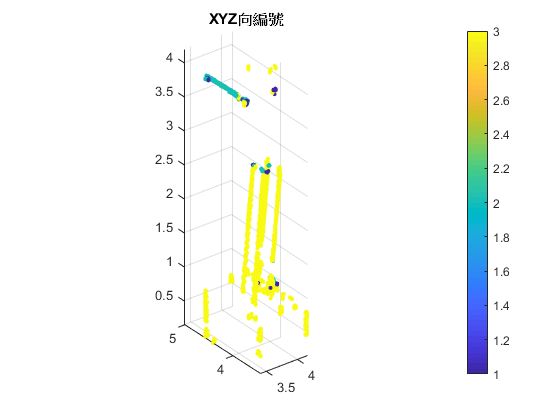

for fi_ii1 = dbnn_group(:,2)'
    aaa = find(dbfi_data(:,5) == fi_ii1);
    group_N(fi_ii1,1) = size(aaa,1);
    dbfi_data(aaa,5) = ones(size(aaa))*dbnn_group(c,3);
    c=c+1;
end

figure(1)
scatter3(db_data(:,1),db_data(:,2),db_data(:,3),10,db_data(:,4),'filled')
title('XYZ向編號');
colorbar
axis equal

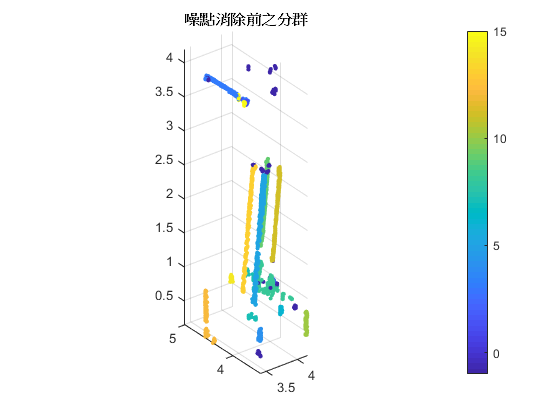


figure(2)
scatter3(db_data(:,1),db_data(:,2),db_data(:,3),10,db_data(:,5),'filled')
title('噪點消除前之分群');
colorbar
axis equal

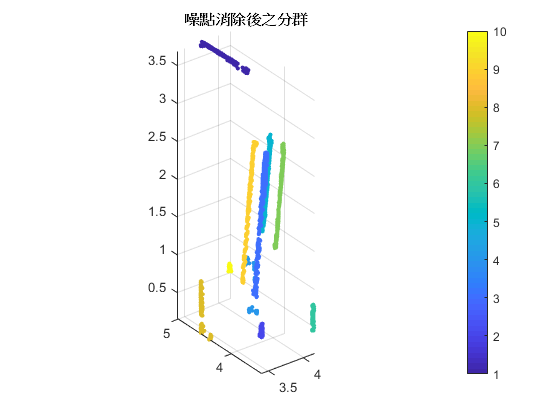


figure(3)
scatter3(dbfi_data(:,1),dbfi_data(:,2),dbfi_data(:,3),10,dbfi_data(:,5),'filled')
title('噪點消除後之分群');
colorbar
axis equal


c = 1

c = 1

for i = 1:1:max(dbfi_data(:,5))
    bbb = find(dbfi_data(:,5)==i)
    group_N(i,2) = size(bbb,1)
end

bbb =         1062
        1063
        1064
        1065
        1066
        1067
        1068
        1069
        1070
        1071


group_N =      0   132
     0     0
   132     0
    67     0
   434     0
     0     0
    59     0
     0     0
   303     0
    59     0


bbb =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


group_N =      0   132
     0    67
   132     0
    67     0
   434     0
     0     0
    59     0
     0     0
   303     0
    59     0


bbb =     22
    30
    31
    32
    33
    34
    35
    36
    37
    38


group_N =      0   132
     0    67
   132   434
    67     0
   434     0
     0     0
    59     0
     0     0
   303     0
    59     0


bbb =    138
   139
   140
   141
   142
   143
   144
   145
   146
   147


group_N =      0   132
     0    67
   132   434
    67    59
   434     0
     0     0
    59     0
     0     0
   303     0
    59     0


bbb =    156
   157
   158
   159
   160
   161
   162
   248
   249
   250


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0     0
    59     0
     0     0
   303     0
    59     0


bbb =    174
   175
   176
   177
   178
   179
   180
   181
   182
   183


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0    59
    59     0
     0     0
   303     0
    59     0


bbb =    199
   200
   201
   202
   203
   204
   205
   206
   207
   208


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0    59
    59   309
     0     0
   303     0
    59     0


bbb =    565
   566
   567
   568
   569
   570
   571
   572
   573
   574


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0    59
    59   309
     0   129
   303     0
    59     0


bbb =    618
   619
   620
   621
   622
   623
   624
   625
   626
   627


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0    59
    59   309
     0   129
   303   302
    59     0


bbb =    635
   636
   637
   638
   639
   640
   641
   642
   643
   644


group_N =      0   132
     0    67
   132   434
    67    59
   434   303
     0    59
    59   309
     0   129
   303   302
    59    41



group_number_finish = max(dbfi_data(:,5));

%   save data_db.mat dbfi_data
%   dlmwrite('G:\論文\1080919\DB_classify\DB_Finish.txt',dbfi_data,'delimiter',' ','newline', 'pc')
%  dlmwrite('G:\論文\1080911\New_DB\DB_Finish.txt',dbfi_data,'delimiter',' ','newline', 'pc')
%    xlswrite('D:\論文\1080911\full\20210415\C6\7F\C6_7F_DB.xlsx',dbfi_data)

toc

Elapsed time is 12.457068 seconds.
